### 2.7.2020 example 

clear,clc;

x = randi(10,1,10)
x0 = x - mean(x);

y = randi(10,1,10)
y0 = y - mean(y);


SX = [];
for i=1:length(x)
    SX(i) = x0(i)^2;
end

% var(x) % <<<<<<<< sample variance (if calc manually, div by n-1 instead of n!)
% sum(SX)/(length(SX)-1)

SXY = [];
for i=1:length(x)
    SXY(i) = x0(i)*y0(i);
end

cov(x,y)
sum(SXY)/(length(SXY)-1)

## ACVF = Compute autocovariance. https://www.mathworks.com/matlabcentral/fileexchange/24066-autocov-m

% % Remove mean from x:
% x = x - mean(x);
% % For faster running time, we pre-allocate the output array:
% acv = zeros(maxlag+1,1);
% % Compute autocovariance:
% for h = 0 : maxlag
%    % Take matrix product of row vector and column vector to obtain a
%    % scalar.  The row vector contains the first m-h elements of x; the
%    % column vector contains the last m-h elements of x.
%    acv(h+1)= x(1:M-h)' * x(1+h:M);
% end
% acv = acv / M;

## another eq from https://atmos.washington.edu/~breth/classes/AM582/lect/lect7-notes.pdf

lag-p ACVF which measures how strongly a time series is related with itself p samples later or earlier

## fit ?

% p = [2 5]; 
% X = 0:20; 
% Yfcn = @(p,X) 1./(1+exp(-p(1).*(X-p(2)))); 
% 
% Y = Yfcn(p,X) + 0.1*randn(size(X)); 
% 	
% [par fit]=fminsearch(@(p) norm(1./(1+exp(-p(1).*(X-p(2)))) -Y), [1,1])
% figure(1)
% plot(X, Y, 'p')
% hold on
% plot(X, Yfcn(par,X), '-r')
% hold off
% grid

% find the parameters where observed values are closest to expected values
% (function)

## youtube

[https://www.youtube.com/watch?v=1aLQNjQcw6s&list=LLvPrUjsGHpkV-ht8Ev8iu8Q&index=9&t=0s](https://www.youtube.com/watch?v=1aLQNjQcw6s&list=LLvPrUjsGHpkV-ht8Ev8iu8Q&index=9&t=0s)

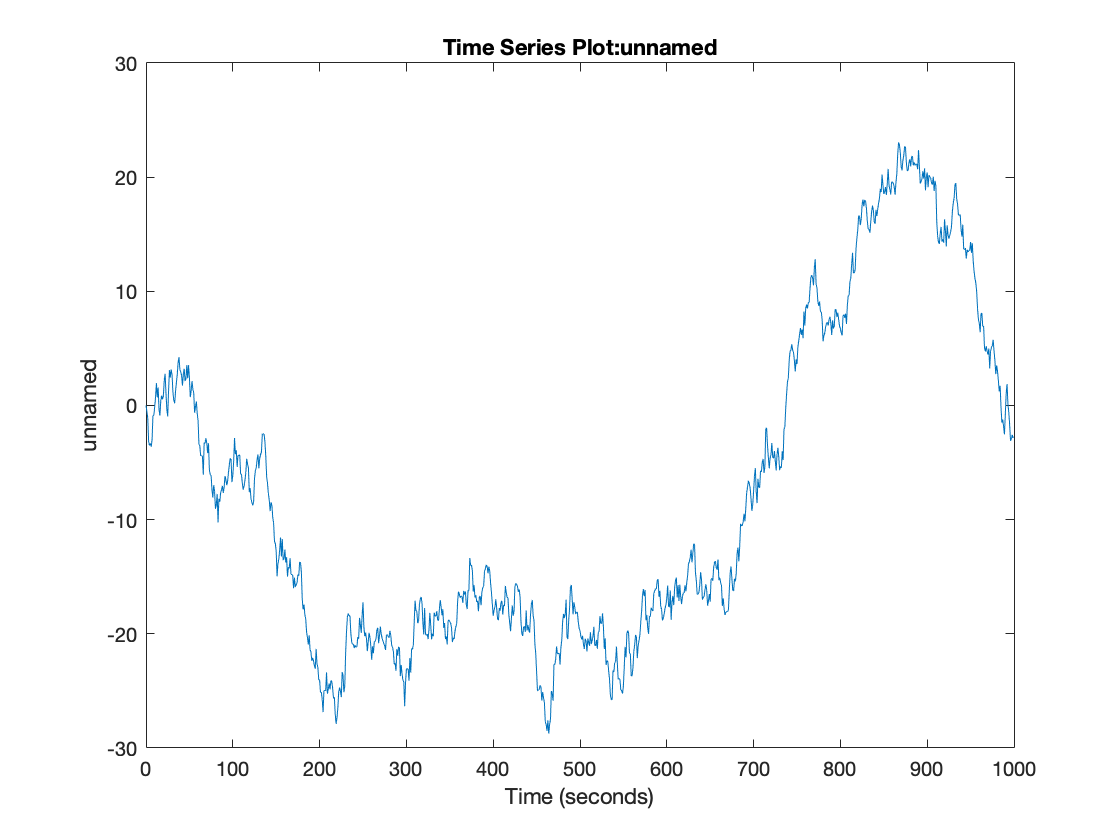

x = [];
x(1) = 0;
for i = 2:1000
    x(i) = x(i-1)+normrnd(0,1);
end

rndwalk = timeseries(x);
plot(rndwalk);

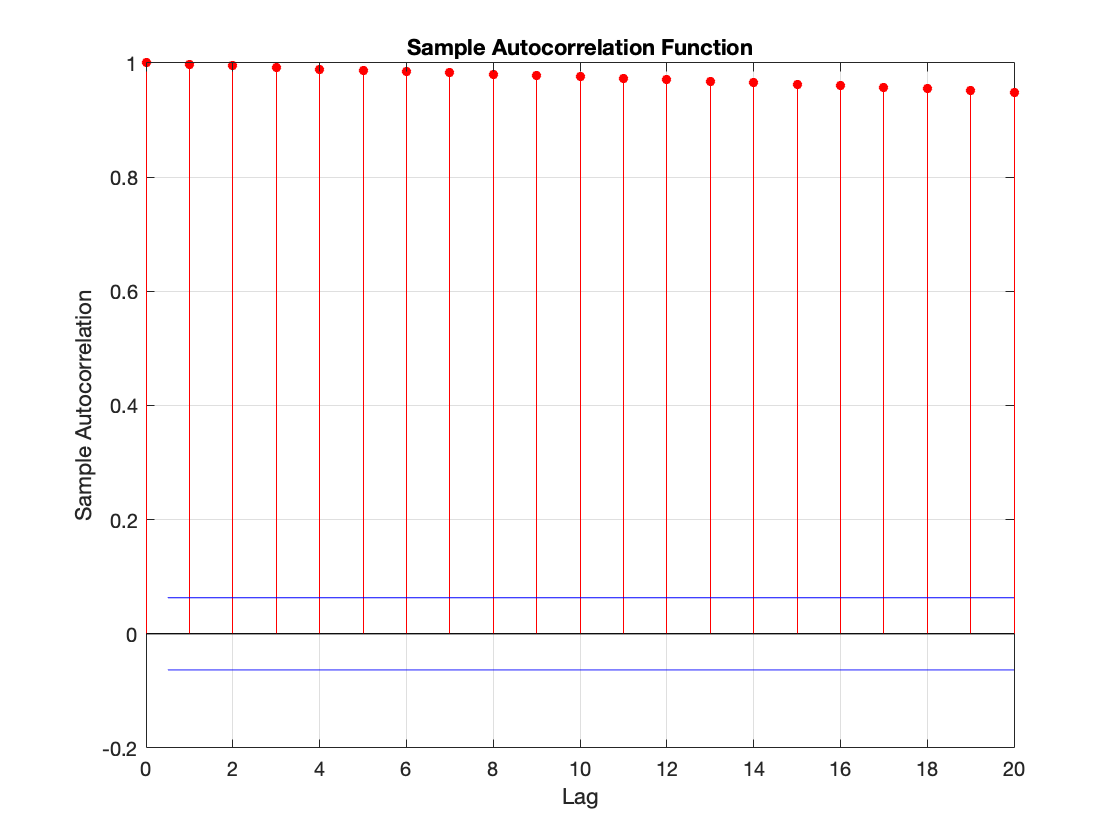

autocorr(x)

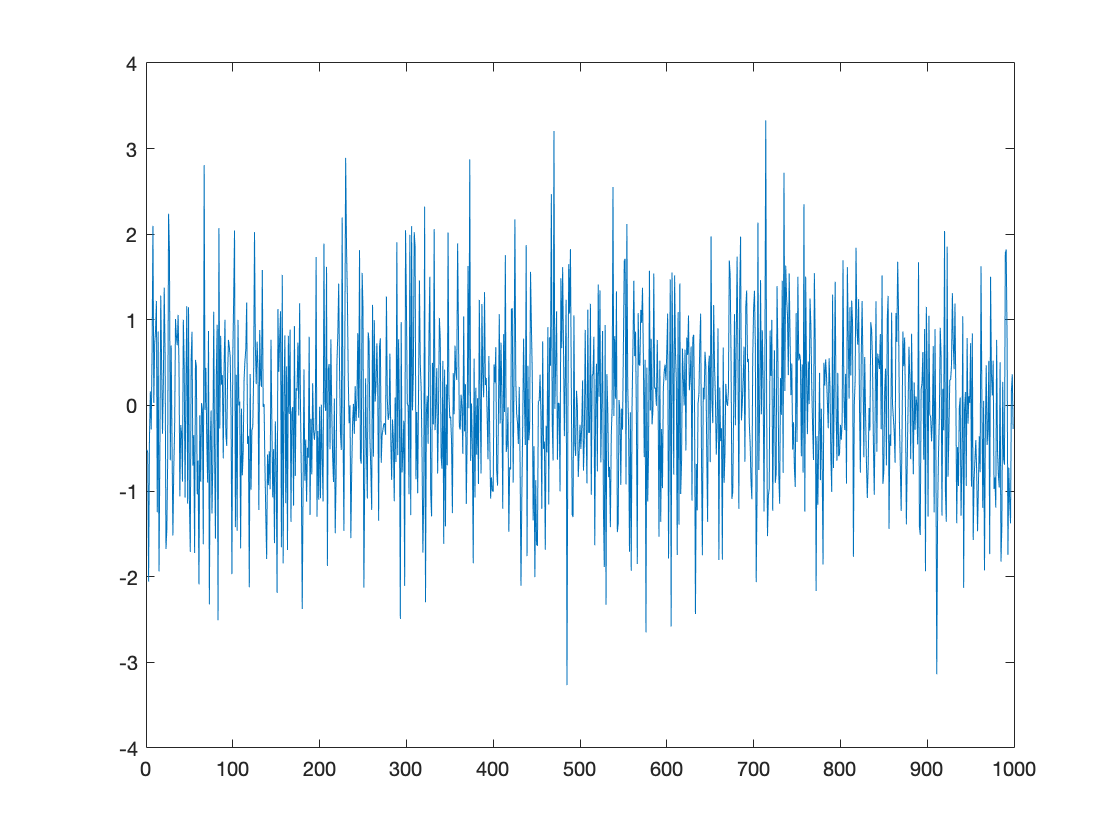


% it is not stationary >> no point of taking ACF >> remove trend by diff

plot(diff(x))

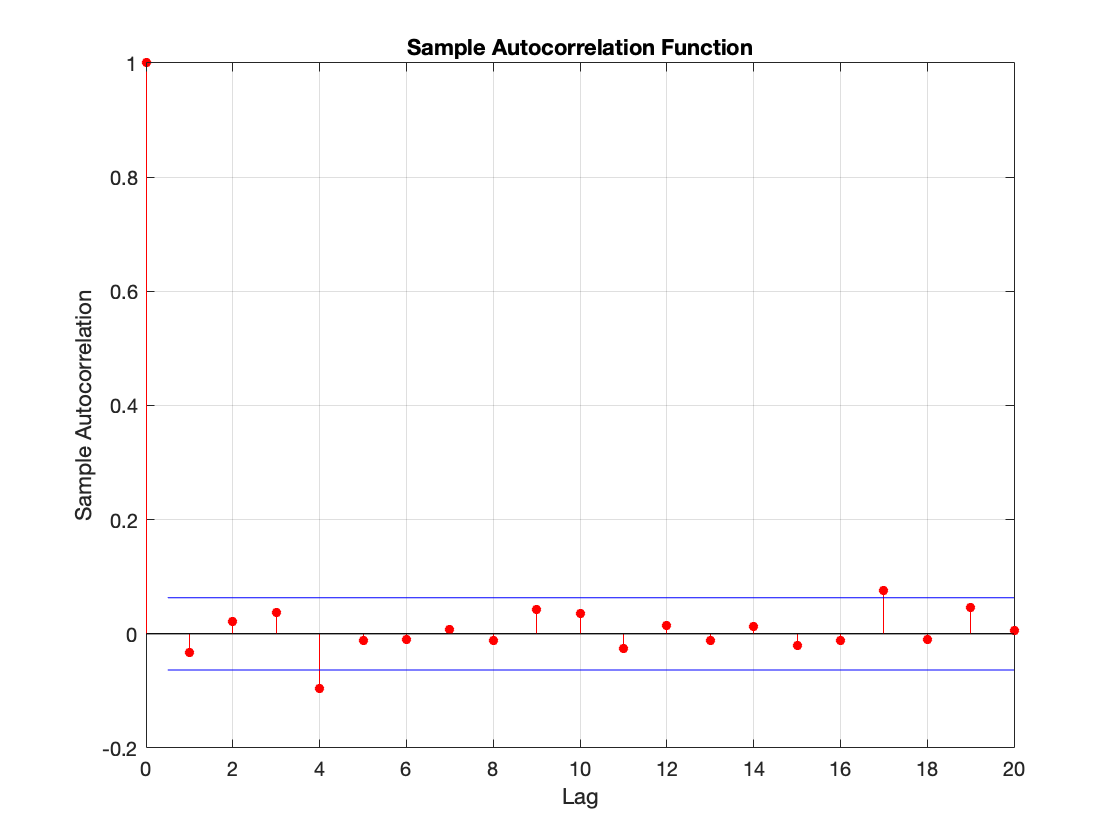

autocorr(diff(x))

Olivia's querry

I = randi(10,1,100);
n = length(I);

I_0 = I(1:n-1);

I_1 = I(2:n);

var(I)

var(I_0)

var(I_1)

lag1cov = cov(I_0,I_1);
lag1cov(1,2)

[rho, pval] = corrcoef(I_0,I_1);
rho(1,2)

sqrt( var(I(1:(n-1)))*var(I(2:n)) )
std(I_0) * std(I_1)

lag1cov(1,2)/sqrt( var(I(1:(n-1)))*var(I(2:n)) )





